### **Digital Signal Processing / AVE** 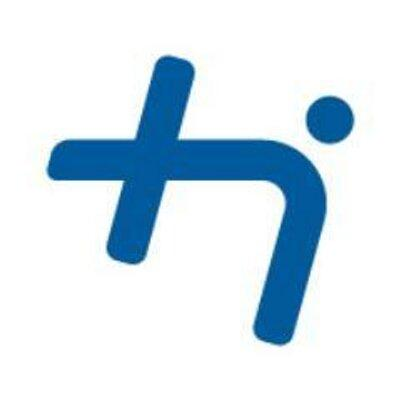

#### **Prof. Dr. Michael Mecking** 

# **Convolution and Frequency Selective Filters**

Given a linear, time invariant (LTI) system with impulse response $h[n]$, the output signal $y[n]$ can be evaluated based on the input signal $x[n]$ by the convolution sum

$y[n] = \sum_{k=-\infty}^{\infty} x[k] \, h[n-k] =: x[n] * h[n]$````````````````````````````

In case the system is causal, the impulse response $h[n]$ is zero for negative $n$. In case the input signal $x[n]$ is also a causal signal, i.e., zero for negative $n$, the output can be computed by the relationship

$y[n] = \sum_{k=0}^n x[k] \, h[n-k]$.

Using MATLAB, the standard unit impulse signal $\delta[n]$ is simply described as $x=[1]$. As another example, a rectangular signal $x[n]$ of five unit samples starting at $n=0$ is described by $x = [1 1 1 1 1]$. We interpret the first element of a signal vector $x$ as the sample at time instant $n=0$.

## **Your Convolution-Function**

### **Problem 1.1**

Write a code to evaluate a convolution $y[n] = x[n] * h[n]$ of two causal, finite duration signals $x[n]$ and $h[n]$. 

Make your mind up about the **duration** of the convolution of two finite duration signals $x[n]$ and $h[n]$. If the duration of $x$ and $h$ are $L_x$ and $L_h$, respectively, what is the duration $L_y$ of $y$?

Work out your code for this setup. Assume that both the signal as well as the impulse repsonse "start" at $n=0$, i.e., assume a causal signal and system. 

**Mind:** 

In MATLAB, this first sample is addressed using $x(1)$ not $x(0)$ as, e.g., in most programming languages. MATLAB uses the mathematical notation addressing the first element in the vector $x$.

Using ChatGPT or CodePilot is an easy means to find the convolution, but pretty useless for DSP-students! You want to learn und understand, so don't use these tools for the lab exercises! To quote Richard W. Hamming:

*"The purpose of computing is insight, not numbers."*

% convolution of two finite duration signals x and h 
% (both starting at n=0)
x = [1 2 3 4];
h = [1 1/2 -1 -1/2 -1];

% your code... 
[L_x,L_h,L_y,y] = my_conv(x,h);


% you may plot your signal using the stem-function.
% stem(0:1:length(y)-1, y)


% a plot of the signals using stem-function


% append zeros to equalise length

% Colour setting
red   = [.8  0  0];    
green = [0.4660 0.6740 0.1880];
blue  = [0 0.4470 0.7410];
grey  = [.5 .5 .5];

x = [x, zeros(1,L_h-1)];
h = [h, zeros(1,L_x-1)];

clf;
n = 0 : 1 : L_y-1;

figure('Position', [100 100 600 800]);  % [x y width height]
subplot(3,1,1)
s = stem(n, x, 'LineWidth', 1.5, 'MarkerSize', 8);
s.Color = blue; 
s.MarkerFaceColor = blue;
grid
set(gca,'FontSize', 15)
ylabel("$x[n]$", Interpreter="latex")
title("convolution of two signals $x[n]$ and $h[n]$", Interpreter="latex")

subplot(3,1,2)
s = stem(n, h, 'LineWidth', 1.5, 'MarkerSize', 8);
s.Color = red; 
s.MarkerFaceColor = red;
grid
set(gca,'FontSize', 15)
ylabel("$h[n]$", Interpreter="latex")

subplot(3,1,3)
s = stem(n, y, 'LineWidth', 1.5, 'MarkerSize', 8);
s.Color = green; 
s.MarkerFaceColor = green;
grid
set(gca,'FontSize', 15)
xlabel("$n$", Interpreter="latex")
ylabel("$y[n]$", Interpreter="latex")

### Problem 1.2

Verify (i.e., visually check the plot above) that the minimum of the signal $y[n]$ occurs at $n=5$with $\min y[n] = -7.5$. If you can confirm this with your code, it’s very unlikely you’ve made an error. ;-)

If your code works, refactor it into a function called *my_conv* for later use. You’ll store a local my_conv.m file with your MATLAB code. Mark the part of the code that should become the function and click **Refactor** in the menu bar. Follow MATLAB’s guidance (modify as necessary) to set up the usage of your function, *my_conv*.

The function can then be used whenever your current working directory (check command *pwd* in the Command Window) matches the location where you store your file. 

## **The Moving-Average System**

The moving-average system will be analysed. A moving average system applies a sliding rectangular window over the input sequence, producing an output that is the average value of the signal samples within the window.

The causal moving-average system’s input/output relationship, as defined in the lecture, is given by ($M_1=0$):

$y[n] = \frac{1}{M_2 + 1} \, \sum_{k=0}^{M_2} x[n-k]$,

This means the average is taken over the current as well as past $M_2$ samples. Consequently, the impulse response $h[n]$ of this moving-average system is:

$h[n] = \frac{1}{M_2 + 1}$ for $0 \le n \le M_2$, and $0$ otherwise.

The following signal $x[n]$ consisting of seven consecutive sine-signals of increasing frequencies $\Omega_k = \frac{\pi}{8}k, \ 1 \le k \le 7,$ will be used as input signal. 

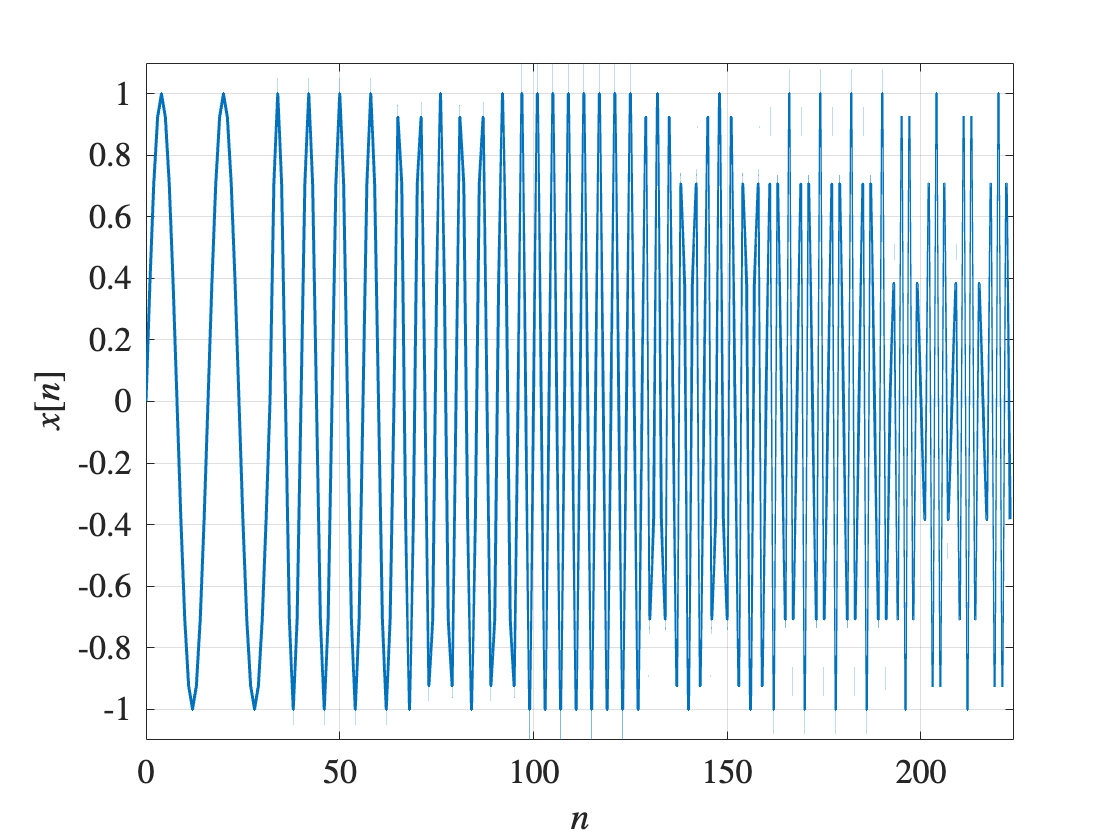

% generate seven sine-signals with equally spaced frequencies Omega_k
% the length of each sine is N samples
% start with N = 32!
N = 32;
n_sub = 0 : N-1;
Omega = (1 : 1 : 7)/8 * pi;

% generate concatenation of individual sine-signals
x = [];
for k = 1:1:7
    % generate samples of each sine
    x_new = sin( Omega(k) * n_sub );

    % append new signal to previous signals x
    x = [x x_new];
end

% plot the input signal x[n] 
% mind, we plot as if x[n] were a continuous-time signal.
% It is not - the signal x is dicrete-time and only exists 
% for discrete time instants!

figure
n = 0 : 7*N-1;
plot(n, x, 'LineWidth', 1.5, 'Color', blue)
axis([0 7*N -1.1 1.1])
set(gca,'TickLabelInterpreter', 'latex')
grid
set(gca,'FontSize', 17)
xlabel("$n$", Interpreter="latex")
ylabel("$x[n]$", Interpreter="latex")

### Problem 2.1

Use the **causal moving average system** with $M_2=4$ to filter the signal $x[n]$: 

Use the impulse response $h_1[n]$ of the moving-average system and apply your *my_conv* function to compute the system output signal $y_1[n]$ which is the convolution of the input signal $x[n]$ and the impulse response $h_1[n]$.

Compare the output signal $y_1[n]$ to the original input signal $x[n]$ to describe the change in the output.

Modify the variable $M_2$ and observe the changes in the output signal. In particular, look at how the output changes for $M_2=4$ and $M_2 = 7$. Interpret the results for these values.

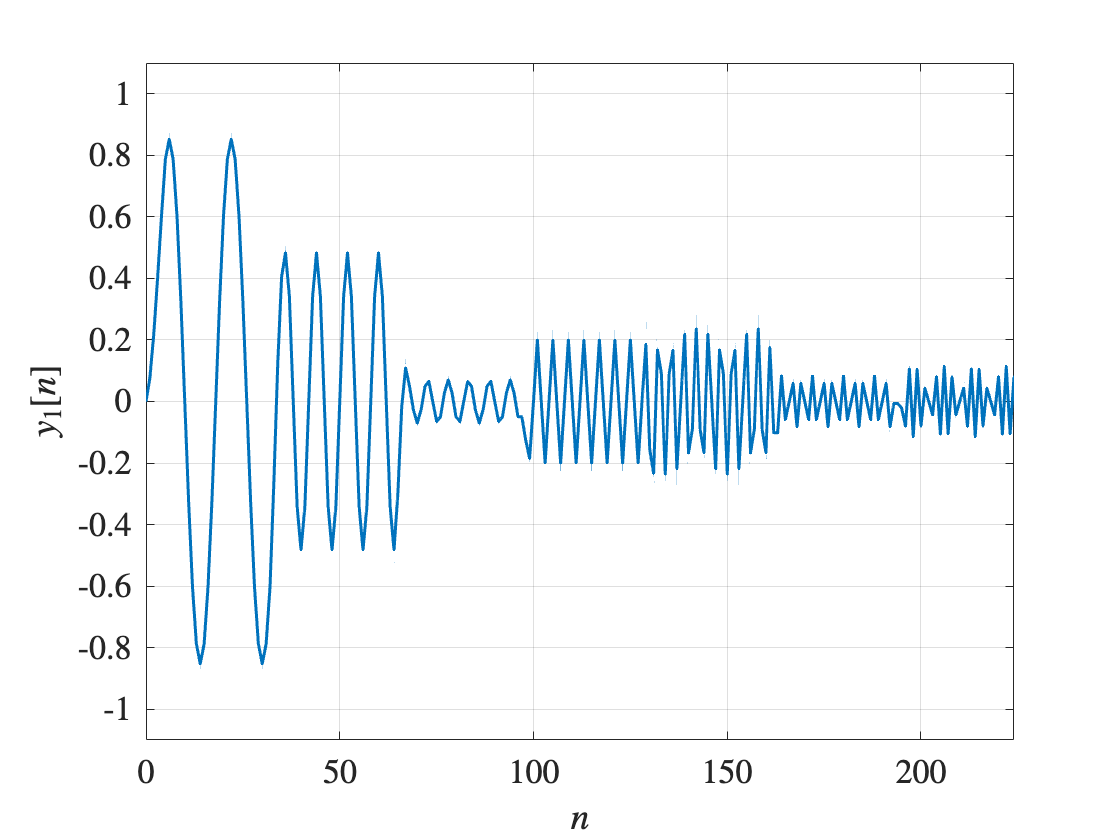

% apply moving average system to the signal x[n]
M2 = 4;

% your code...

L = M2 + 1;            
h1 = (1/L) * ones(1, L);  
[L_x,L_h,L_y,y] = my_conv(x, h1);

nx = 0 : length(x) - 1 ;
ny = 0 : length(y) - 1 ;

% plot the output signal y1[n] of the moving-average filter
% rename y1 appropriately in case you called the output of the system
% differently
 figure
 plot (ny, y , 'LineWidth', 1.5, 'Color', blue)
 axis([0 7*N -1.1 1.1])
 set(gca,'TickLabelInterpreter', 'latex')
 grid on
 set(gca,'FontSize', 17)
 xlabel("$n$", Interpreter="latex")
 ylabel("$y_1[n]$", Interpreter="latex")

### Problem 2.2

Modify the moving average system slightly and observe the output of the new system:

Use an impulse response $h_2[n]$ that is of opposite sign than $h_1[n]$ for the odd discrete-time instants:

$h_2[n] = (-1)^n \, h_1[n]$.

For example, if $M_2 = 2$, the moving average filter in 2.1 computes $y[n] = \frac{1}{3} (x[n] + x[n-1] + x[n-2])$ but this filter  computes

$y[n] = \frac{1}{3} (x[n] - x[n-1] + x[n-2])$.

Create the output signal $y_2[n]$ by processing the original input signal $x[n]$ with the modified moving average system $h_2[n]$.

% apply modified moving average system to original signal x[n]
M2 = 4;
L = M2 + 1;            
h2 = (1/L) * ones(1, L)

h2 =     0.2000    0.2000    0.2000    0.2000    0.2000



% your code...
for p = 1:length(h2)
    h2(p) = (-1)^p * h2(p);
end  
[L_x,L_h,L_y,y] = my_conv(x, h2);

nx = 0 : length(x) - 1 ;
ny = 0 : length(y) - 1 ;

% plot the output signal y2[n] of the modified moving-average filter
 figure
 plot (ny, y, 'LineWidth', 1.5, 'Color', red)
 axis([0 7*N -1.1 1.1])
 set(gca,'TickLabelInterpreter', 'latex')
 grid
 set(gca,'FontSize', 17)
 xlabel("$n$", Interpreter="latex")
 ylabel("$y_2[n]$", Interpreter="latex")

### **Problem 2.3**

The **frequency response** $H(e^{j\Omega})$ of a discrete-time filter with impulse response $h[n]$ is given by


$$H(e^{j\Omega}) = \sum_{n=-\infty}^{\infty} h[n] \, e^{-j \Omega n} .$$


The following code evaluates the frequency responses $H_1{e^{j\Omega})$ and $H_2(e^{j\Omega})$ of the two moving average systems considered above. Try to understand how the code evaluates the frequency response.

How can you explain the observed behaviour of the (modified) moving average filter using the frequency response graphs?

In particular, how can you explain the output signal of the moving average filter for $M_2 = 7$ (and $M_2 = 15$) for the special signal $x[n]$ in use?

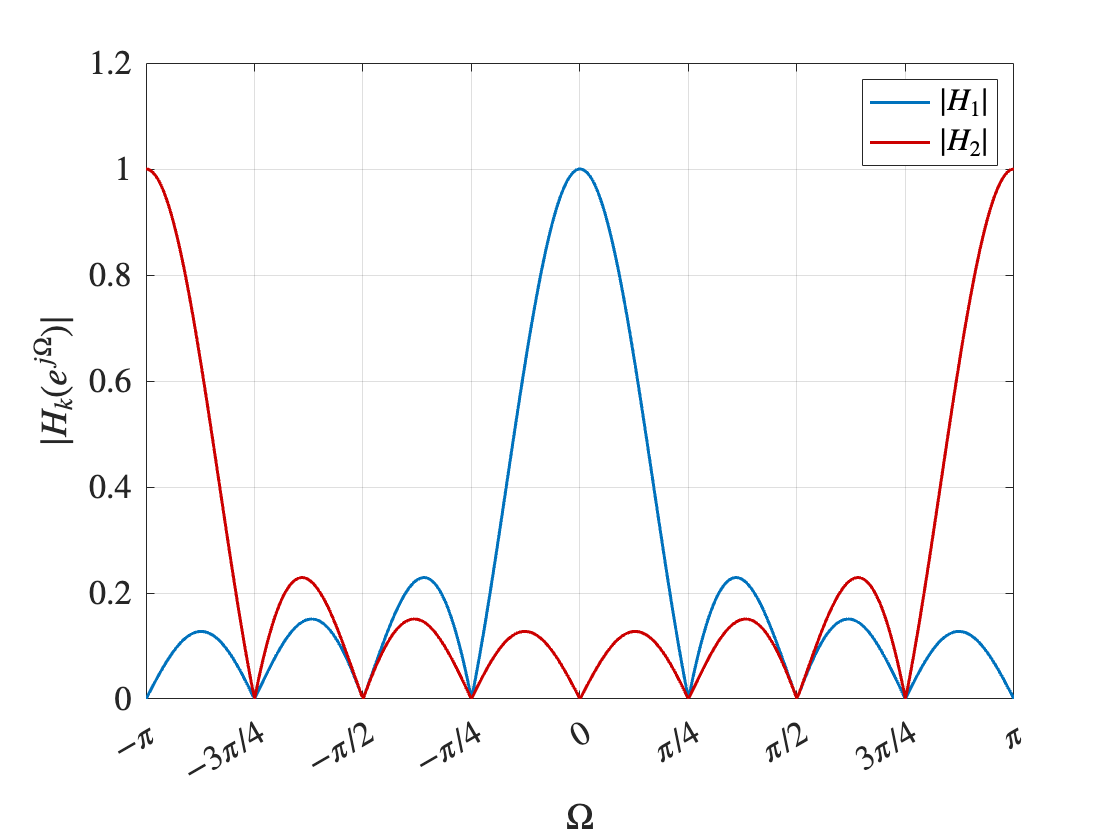

% evaluation of the frequency response of the moving-average system
% setup of variables
M2 = 7;

% create the impulse responses h1 and h2
h1 = 1/(M2+1) * ones(1, M2+1);
k  = 0 : 1 : length(h1)-1;
h2 = (-1).^k .* h1;

% evaluation of the frequency response H along the unit circle (from -pi to pi):
num   = 512;
Omega = linspace(-pi, pi, num);

% evaluation of the frequency response H1 
helper1 = exp(-1j * k' * Omega);
helper2 = h1' * ones(1, num);
H1 = sum( helper1 .* helper2 );

% ... the same computation yet again for H2
helper2 = h2' * ones(1, num);
H2 = sum( helper1 .* helper2 );

% plot the magnitude responses of H1 and H2
plot(Omega, abs(H1), 'LineWidth', 1.5, 'Color', blue)
hold on
plot(Omega, abs(H2), 'LineWidth', 1.5, 'Color', red)

axis([-pi pi 0 1.2])
xticks([-pi -3/4*pi -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi])
xticklabels({'$-\pi$','$-3\pi/4$','$-\pi/2$', '$-\pi/4$', '$0$', '$\pi/4$', '$\pi/2$', '$3\pi/4$', '$\pi$'})
set(gca,'TickLabelInterpreter', 'latex')
grid
set(gca,'FontSize', 17)
xlabel("$\Omega$", Interpreter="latex")
ylabel("$|H_k(e^{j\Omega})|$", Interpreter="latex")
legend("$|H_1|$", "$|H_2|$", Interpreter = "latex")

hold off

## The Chirp-Signal

### Problem 3.1

Let’s generate and filter a sine signal with a sweeping instantaneous frequency that continuously increases throughout the signal’s duration starting at  $f=0$ at $n=0$. This type of signal is known as a “chirp”.

% generation of the signal c[n] as a chirp:

% chirp definition from MATLAB documentation:
% c = chirp(t,f0,t1,f1) generates samples of a linear swept-frequency cosine signal 
% at the time instances defined in array t. 
% The instantaneous frequency at time 0 is f0 and the instantaneous frequency at 
% time t1 is f1.

% this means, that we'll take 2000 samples each second
% for an overall duration of 5 seconds.
fs       = 2000;
duration = 5;
t = 0 : 1/fs : duration;      

% generate the chirp signal c[n] using the MATLAB function chirp
% and the vector t of sampling time-instants
% your code...
t1 = 1;               
f1 = 200;             
c    = chirp(t, 0, t1, f1);

You may listen to the chirp signal (with your headphones) by using the following code:

% provide chirp signal to sound-card
 sound(c, fs)

### Problem 3.2

Filter the chirp signal $c[n]$ using your moving average filters $h_1[n]$ and $h_2[n]$. Listen to the output signals of both filters. Can you identify the frequency responses $H_1(e^{j\Omega})$ and $H_2(e^{j\Omega})$ using your audio senses? 

Use $M_2 = 7$ and run the  code cells of Problems 2.1 and 2.2  to create the frequency responses $h_1[n]$ and $h_2[n]$!

% if you listen to multiple audio signals,
% use pause(6) to create a pause between the outputs.

% mind which version of h1 and h2 you are using!!   
% choose M2 = 7 for your analysis in this problem and 
% re-evaluate h1 and h2 in your code cells above

% your code...
function [L_x,L_h,L_y,y] = my_conv(x,h)
L_x = length(x);
L_h = length(h);
L_y = L_x + L_h - 1;



y = zeros(1, L_y);


for n = 1:L_y
    for k = 1:L_x
        if (n-k+1 > 0) && (n-k+1 <= L_h)
            y(n) = y(n) + x(k) * h(n-k+1);
        end
    end
end
end